format shortg
clearvars all

# Oppgave 1

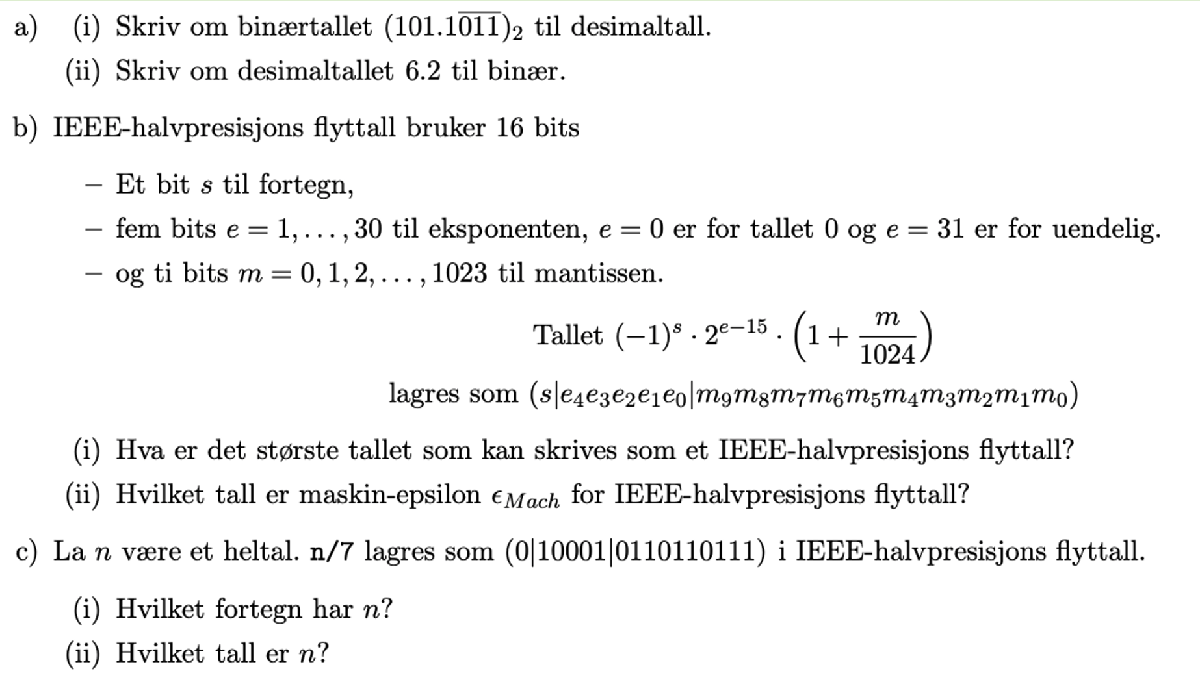

## a)

### (i)

heltallsdel: $101=2^2 +2^0 =4+1=5$

desimaldel: $\begin{array}{l}
0\ldotp 1\bar{011} =0\ldotp 1011011011\ldotp \ldotp \ldotp \ldotp \\
7x=101=5\\
x=\frac{5}{7}=0\ldotp 71428
\end{array}$

5+5/7

ans =        5.7143


### (ii)

heltallsdel: $6=2^2 +2^1 =110$

desimaldel: $\begin{array}{l}
2*0\ldotp 2=0\ldotp 4+0\\
2*0\ldotp 4=0\ldotp 8+0\\
2*0\ldotp 8=0\ldotp 6+1\\
2*0\ldotp 6=0\ldotp 2+1
\end{array}$


$$6\ldotp 2_{10} =110\ldotp {\bar{0011} }_2$$
 

## b)

### (i) 

største tallet blir $1*2^{30-15} *\left(1+\frac{1023}{1024}\right)=1*2^{15} *\left(1+\frac{1023}{1024}\right)$

2^15*(1+1023/1024)

ans =        65504


### (ii)

minste tallet vi kan skrive er $e_{\textrm{mach}} =\frac{1}{1024}$

1/1024

ans =    0.00097656


## c)

### (i) positivt

### (ii)


$$\frac{n}{7}=1*2^{{10001}_2 -{15}_{10} } *\left(1+\frac{{0110110111}_2 }{1024}\right)=1*2^{17-15} *\left(1+\frac{439}{1024}\right)$$


n = 7 * (2^(17-15)*(1+439/1024))

n =        40.004


# Oppgave 2

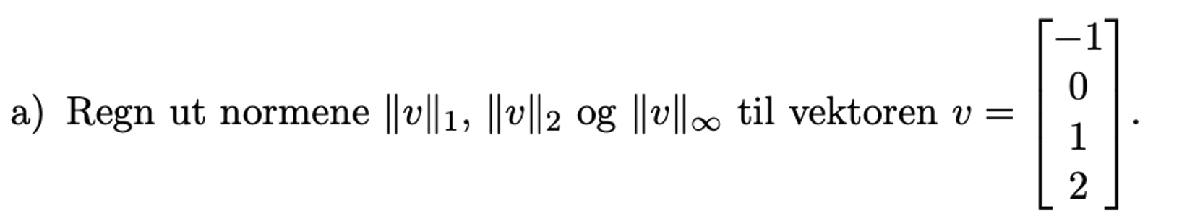


$$\begin{array}{l}
{\left|\left|v\right|\right|}_1 =\sqrt[1]{1^1 +0^1 +1^1 +2^1 }=4\\
{\left|\left|v\right|\right|}_2 =\sqrt[2]{1^2 +0^2 +1^2 +2^2 }=\sqrt{6}\\
{\left|\left|v\right|\right|}_{\infty } =\max \left\lbrace 1,0,1,2\right\rbrace =2
\end{array}$$



$$u=\textrm{fft}\left(\left\lbrack \begin{array}{c}
-1\\
0\\
1\\
2
\end{array}\right\rbrack \right)=M_4 v$$



$$\begin{array}{l}
w_0 =M_2 \left\lbrack v_0 \;v_2 \right\rbrack =\left\lbrack \begin{array}{cc}
1 & 1\\
1 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
-1\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
-2
\end{array}\right\rbrack \\
w_1 =M_2 \left\lbrack v_{1\;} v_3 \right\rbrack =\left\lbrack \begin{array}{cc}
1 & 1\\
1 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
-2
\end{array}\right\rbrack 
\end{array}$$



$$\textrm{fft}\left(v\right)=\left\lbrack \begin{array}{c}
u_0 \\
u_1 \\
u_2 \\
u_3 
\end{array}\right\rbrack =$$

$$\begin{array}{l}
\left\lbrack \begin{array}{c}
u_0 \\
u_1 
\end{array}\right\rbrack =w_0 +\left\lbrack \begin{array}{cc}
1 & 0\\
0 & -i
\end{array}\right\rbrack w_1 =\left\lbrack \begin{array}{c}
0+1*2\\
-2+-i*-2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
-2+2i
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
u_3 \\
u_4 
\end{array}\right\rbrack =w_0 +\left\lbrack \begin{array}{cc}
-1 & 0\\
0 & i
\end{array}\right\rbrack w_1 =\left\lbrack \begin{array}{c}
0+-1*2\\
-2+i*-2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-2\\
-2-2i
\end{array}\right\rbrack 
\end{array}$$

$$=\left\lbrack \begin{array}{c}
2\\
-2+2i\\
-2\\
-2-2i
\end{array}\right\rbrack$$


fft([-1, 0, 1, 2]')

ans =             2 +          0i
           -2 +          2i
           -2 +          0i
           -2 -          2i


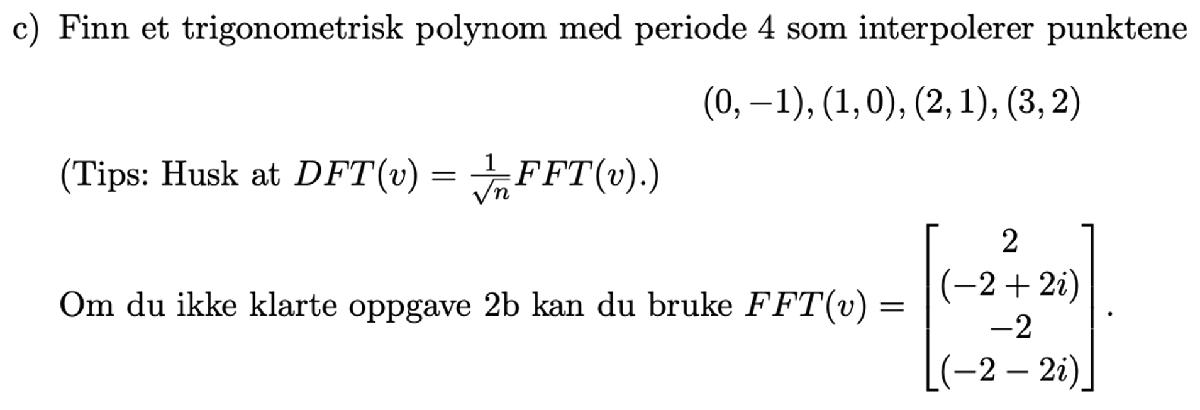


$$\textrm{vi}\;\textrm{har}\;c\left(\textrm{start}\right)=0\;\textrm{og}\;d\left(\textrm{slutt}\right)=4,\textrm{altså}\;n=4$$



$$\textrm{DFT}\left(v\right)=\frac{1}{\sqrt{n}}\left\lbrack \begin{array}{c}
2\\
-2+2i\\
-2\\
-2-2i
\end{array}\right\rbrack =\frac{1}{\sqrt{4}}\left\lbrack \begin{array}{c}
2\\
-2+2i\\
-2\\
-2-2i
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
-1+i\\
-1\\
-1-i
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{cc}
a_0  & b_0 \\
a_1  & b_1 \\
a_2  & b_2 \\
a_3  & b_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0\\
-1 & 1\\
-1 & 0\\
-1 & -1
\end{array}\right\rbrack$$


Formel for trigonometrisk interpolasjon:


$$\begin{array}{l}
P_n \left(t\right)=\frac{a_0 }{\sqrt{n}}+\frac{2}{\sqrt{n}}\sum_k^{\frac{n}{2}-1} \left(a_k \cos \left(\frac{2\pi k\left(t-c\right)}{d-c}\right)-b_k \sin \left(\frac{2\pi k\left(t-c\right)}{d-c}\right)\right)+\frac{a_{n/2} }{\sqrt{n}}\cos \left(\frac{n\pi \left(t-c\right)}{d-c}\right)\\
P_4 \left(t\right)=\frac{a_0 }{\sqrt{4}}+\frac{2}{\sqrt{4}}\sum_k^{\frac{4}{2}-1} \left(a_k \cos \left(\frac{2\pi k\left(t-0\right)}{4-0}\right)-b_k \sin \left(\frac{2\pi k\left(t-0\right)}{4-0}\right)\right)+\frac{a_{4/2} }{\sqrt{4}}\cos \left(\frac{4\pi \left(t-0\right)}{4-0}\right)\\
P_4 \left(t\right)=\frac{a_0 }{2}+\sum_k^1 \left(a_k \cos \left(\frac{\pi \textrm{kt}}{2}\right)-b_k \sin \left(\frac{\pi \textrm{kt}}{2}\right)\right)+\frac{a_2 }{2}\cos \left(\pi t\right)\\
P_4 \left(t\right)=\frac{a_0 }{2}+a_1 \cos \left(\frac{\pi t}{2}\right)-b_1 \sin \left(\frac{\pi t}{2}\right)+\frac{a_2 }{2}\cos \left(\pi t\right)\\
\\
P_4 \left(t\right)=\frac{1}{2}-\cos \left(\frac{\pi t}{2}\right)-\sin \left(\frac{\pi t}{2}\right)-\frac{1}{2}\cos \left(\pi t\right)
\end{array}$$


# Oppgave 4

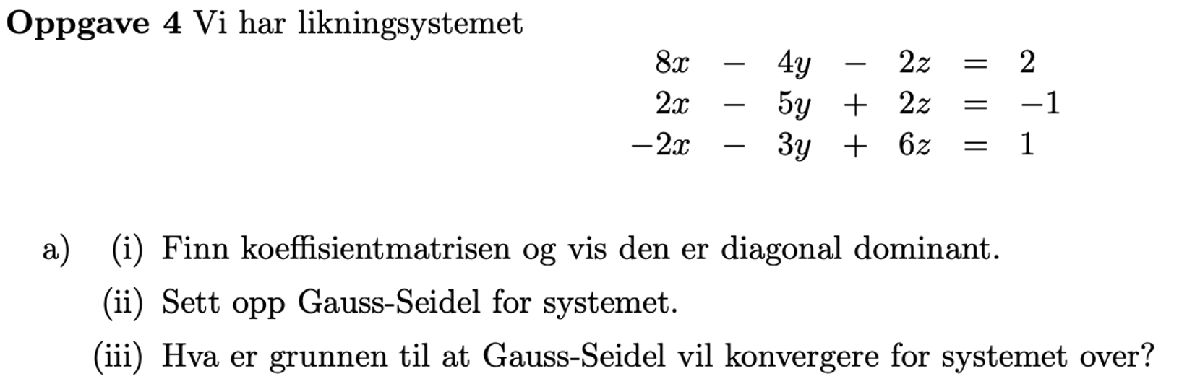

#### (i) $\left\lbrack \begin{array}{ccc}
8 & -4 & -2\\
2 & -5 & 2\\
-2 & -3 & 6
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{cc}
a_{11} =8 & a_{12} +a_{13} =6\\
a_{22} =5 & a_{21} +a_{23} =4\\
a_{33} =6 & a_{31} +a_{32} =5
\end{array}\right\rbrack$

vi ser at at $a_{11} ,a_{22\;} \textrm{og}\;a_{33}$ er større en summen av absoluttverdien av de andre i raden, altså er diagonalen dominant.

#### (ii)


$$\begin{array}{l}
8x-4y-2z=2\;\;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;x=\frac{2+4y+2z}{8}\;\;\;\;\;\;\;\;\Rightarrow \;\;x_{i+1} =\frac{2+4y_i +2z_i }{8}\;\;\;\\
2x-5y+2z=-1\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;y=\frac{1+2x+2z}{5}\;\;\;\;\;\;\;\;\Rightarrow y_{i+1} =\frac{1+2x_{i+1} +2z_i }{5}\;\;\;\;\;\;\;\;\\
-2x-3y+6z=1\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;z=\frac{1+2x+3y}{6}\;\;\;\;\;\;\;\;\;\Rightarrow z_{i+1} =\frac{1+2x_{i+1} +3y_{i+1} }{6}\;\;\;\;\;
\end{array}$$


#### (iii)

Gauss-Seidel vil konverge fordi matrisen er diagonal dominant, dette er fordi......

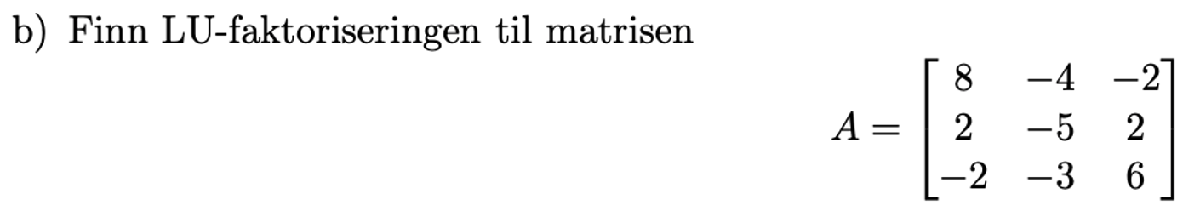


$$L*U=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
8 & -4 & -2\\
2 & -5 & 2\\
-2 & -3 & 6
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
1/4 & 1 & 0\\
-1/4 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
8 & -4 & -2\\
0 & -4 & 5/2\\
0 & -4 & 11/2
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
1/4 & 1 & 0\\
-1/4 & 1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
8 & -4 & -2\\
0 & -4 & 5/2\\
0 & 0 & 3
\end{array}\right\rbrack$$


A = [ 8 -4 -2;
	  2 -5  2;
	 -2 -3  6];
 
 [L, U] = LU_faktoriser(A)

L =             1            0            0
         0.25            1            0
        -0.25            1            1


U =             8           -4           -2
            0           -4          2.5
            0            0            3


# Oppgave 5

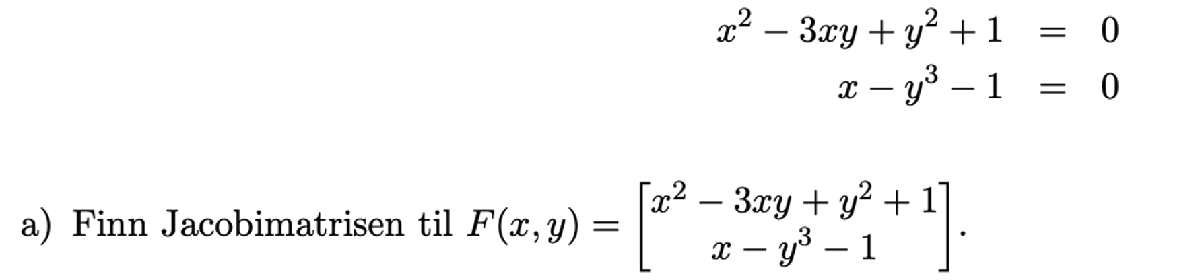


$$\mathrm{DF}=\left\lbrack \begin{array}{cc}
\frac{d}{\textrm{d}x}\left(x^2 -3\mathrm{xy}+y^2 +1\right) & \frac{d}{\textrm{d}y}\left(x^2 -3\mathrm{xy}+y^2 +1\right)\\
\frac{d}{\textrm{d}x}\left(x-y^3 -1\right) & \frac{d}{\textrm{d}y}\left(x-y^3 -1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
2x-3y & -3x+2y\\
1 & -3y^2 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
x_{i+1} \\
y_{i+1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
y_i 
\end{array}\right\rbrack -s$$



$$\mathrm{DF}\left(1,1\right)=\left\lbrack \begin{array}{cc}
2*1-3*1 & -3*1+2*1\\
1 & -3{*1}^2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-1 & -1\\
1 & -3
\end{array}\right\rbrack$$


${\left\lbrack \begin{array}{cc}
a & b\\
c & d
\end{array}\right\rbrack }^{-1} =\frac{1}{\mathrm{ad}-\mathrm{bc}}\left\lbrack \begin{array}{cc}
d & -b\\
-c & a
\end{array}\right\rbrack$ (invers av 2x2 matrise)


$${\mathrm{DF}\left(1,1\right)}^{-1} ={\left\lbrack \begin{array}{cc}
-1 & -1\\
1 & -3
\end{array}\right\rbrack }^{-1} =\frac{1}{\left(-1*-3\right)-\left(1*-1\right)}\left\lbrack \begin{array}{cc}
-3 & 1\\
-1 & -1
\end{array}\right\rbrack =\frac{1}{4}\left\lbrack \begin{array}{cc}
-3 & 1\\
-1 & -1
\end{array}\right\rbrack$$



$$F\left(1,1\right)=\left\lbrack \begin{array}{c}
1^2 -3*1*1+1^2 +1\\
1-1^3 -1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1-3+1+1\\
1-1-1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
-1
\end{array}\right\rbrack$$



$$s={\mathrm{DF}\left(1,1\right)}^{-1} F\left(1,1\right)=\frac{1}{4}\left\lbrack \begin{array}{cc}
-3 & 1\\
-1 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
-1
\end{array}\right\rbrack =\frac{1}{4}\left\lbrack \begin{array}{c}
1\\
-1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1/4\\
-1/4
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
x_1 \\
y_1 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_0 \\
y_0 
\end{array}\right\rbrack -s=\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
-1/4\\
1/4
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
5/4\\
3/4
\end{array}\right\rbrack$$
